# VAJA 5 - Stacionarnost signalov

Robert Vičič, 64140173 

Namen vaje je seznaniti se z metodami določanja stacionarnosti signalov. 

## Naloga 1

Test tendenc

Izris signalov :

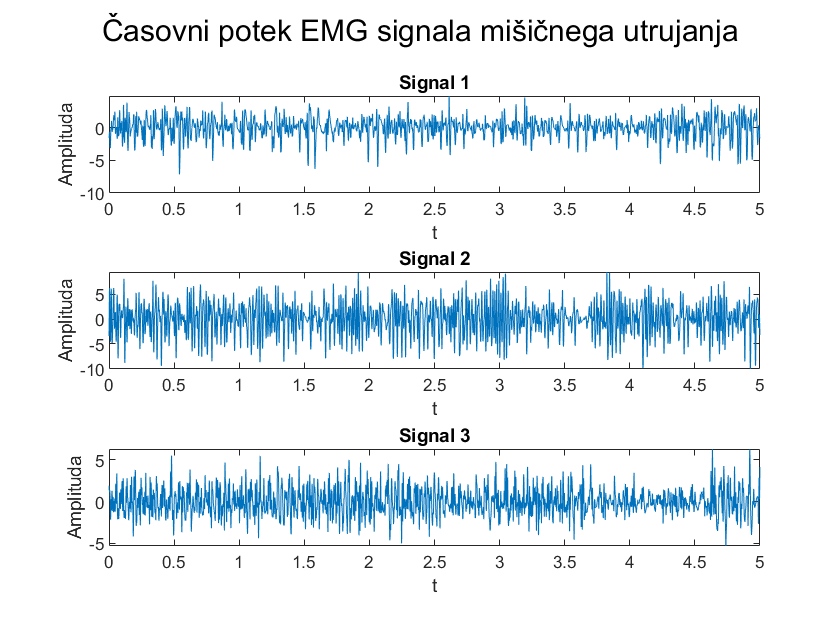

close all; clear all;

A = load('v5_robert_vicic.mat');
N = 10000;
fv = 2000;
t = 0: 1/fv : (N - 1)/fv;

figure
sgtitle('Časovni potek EMG signala mišičnega utrujanja')
subplot(3,1,1)
plot(t, A.Meritve(1).signal)
title('Signal 1'); xlabel('t'); ylabel('Amplituda');
subplot(3,1,2)
plot(t, A.Meritve(2).signal)
title('Signal 2'); xlabel('t'); ylabel('Amplituda');
subplot(3,1,3)
plot(t, A.Meritve(3).signal)
title('Signal 3'); xlabel('t'); ylabel('Amplituda');

Signali mi izgledajo nestacionarni.

Preverjanje stacionarnosti z prvim postopkom (test tendenc):

pec2=A.Meritve(1).signal;
lat2=A.Meritve(2).signal;
pec1=A.Meritve(3).signal;

k=20;
pec2=reshape(pec2(1:end-mod(numel(pec2),k)),floor(numel(pec2)/k),k);
lat2=reshape(lat2(1:end-mod(numel(lat2),k)),floor(numel(lat2)/k),k);
pec1=reshape(pec1(1:end-mod(numel(pec1),k)),floor(numel(pec1)/k),k);


meje=[
10 3 8
12 3 10
14 4 11
20 6 15
50 19 32
100 42 59
];


lat1_mean=mean(pec2);
lat1_var=var(pec2);
lat1_d_mean=sign(lat1_mean-median(lat1_mean));
lat1_d_var=sign(lat1_var-median(lat1_var));
lat1_nT_mean=1+sum(lat1_d_mean(2:end)~=lat1_d_mean(1:end-1))

lat1_nT_mean = 14

lat1_nT_var=1+sum(lat1_d_var(2:end)~=lat1_d_var(1:end-1))

lat1_nT_var = 9

stac_lat1=(lat1_nT_mean > meje(meje(:,1)==k,2))&...
    (lat1_nT_mean < meje(meje(:,1)==k,3))&...
    (lat1_nT_var > meje(meje(:,1)==k,2))&...
    (lat1_nT_var < meje(meje(:,1)==k,3))

stac_lat1 = logical
   1


je stacionaren

lat2_mean=mean(lat2);
lat2_var=var(lat2);
lat2_d_mean=sign(lat2_mean-median(lat2_mean));
lat2_d_var=sign(lat2_var-median(lat2_var));
lat2_nT_mean=1+sum(lat2_d_mean(2:end)~=lat2_d_mean(1:end-1))

lat2_nT_mean = 12

lat2_nT_var=1+sum(lat2_d_var(2:end)~=lat2_d_var(1:end-1))

lat2_nT_var = 13

stac_lat2=(lat2_nT_mean > meje(meje(:,1)==k,2))&...
    (lat2_nT_mean < meje(meje(:,1)==k,3))&...
    (lat2_nT_var > meje(meje(:,1)==k,2))&...
    (lat2_nT_var < meje(meje(:,1)==k,3))

stac_lat2 = logical
   1


je stacionaren

pec1_mean=mean(pec1);
pec1_var=var(pec1);
pec1_d_mean=sign(pec1_mean-median(pec1_mean));
pec1_d_var=sign(pec1_var-median(pec1_var));
pec1_nT_mean=1+sum(pec1_d_mean(2:end)~=pec1_d_mean(1:end-1))

pec1_nT_mean = 17

pec1_nT_var=1+sum(pec1_d_var(2:end)~=pec1_d_var(1:end-1))

pec1_nT_var = 9

stac_pec1=(pec1_nT_mean > meje(meje(:,1)==k,2))&...
    (pec1_nT_mean < meje(meje(:,1)==k,3))&...
    (pec1_nT_var > meje(meje(:,1)==k,2))&...
    (pec1_nT_var < meje(meje(:,1)==k,3))

stac_pec1 = logical
   0


ni stacionaren

Stacionarnost določimo s primerjanjem rezultatov z tabelo.

Z mojo oceno se ujema le zadnji signal, prvi in drugi pa sta se izkazala za stacionarna. To potrjuje teorijo, da je na oko zelo težko določiti stacionarnost.

## Naloga 2

Test statistike T in F

pec2=reshape(pec2,numel(pec2),1);
lat2=reshape(lat2,numel(lat2),1);
pec1=reshape(pec1,numel(pec1),1);

lat1_N1=round(length(pec2)/2);
lat1_N2=length(pec2)-lat1_N1;
lat1_1=pec2(1:lat1_N1);
lat1_2=pec2(1+lat1_N1:lat1_N1+lat1_N2);
lat1_1_mean=mean(lat1_1);
lat1_1_var=var(lat1_1);
lat1_2_mean=mean(lat1_2);
lat1_2_var=var(lat1_2);
T_lat1=(lat1_1_mean-lat1_2_mean)/(sqrt((1/lat1_N1+1/lat1_N2)*...
    (lat1_N1*lat1_1_var+lat1_N2*lat1_2_var)/(lat1_N1+lat1_N2-2)))

T_lat1 = -0.1898

F_lat1=(lat1_1_var*(lat1_N1/(lat1_N1-1)))/(lat1_2_var*(lat1_N2/(lat1_N2-1)))

F_lat1 = 1.0857

stac_lat1=(T_lat1<1.96)&(T_lat1>-1.96)&(F_lat1<1.0229)&(F_lat1>0.9776)

stac_lat1 = logical
   0


ni stacionarn, saj se varianci razlikujeta

lat2_N1=round(length(lat2)/2);
lat2_N2=length(lat2)-lat2_N1;
lat2_1=lat2(1:lat2_N1);
lat2_2=lat2(1+lat2_N1:lat2_N1+lat2_N2);
lat2_1_mean=mean(lat2_1);
lat2_1_var=var(lat2_1);
lat2_2_mean=mean(lat2_2);
lat2_2_var=var(lat2_2);
T_lat2=(lat2_1_mean-lat2_2_mean)/(sqrt((1/lat2_N1+1/lat2_N2)*...
    (lat2_N1*lat2_1_var+lat2_N2*lat2_2_var)/(lat2_N1+lat2_N2-2)))

T_lat2 = -0.1538

F_lat2=(lat2_1_var*(lat2_N1/(lat2_N1-1)))/(lat2_2_var*(lat2_N2/(lat2_N2-1)))

F_lat2 = 1.0270

stac_lat2=(T_lat2<1.96)&(T_lat2>-1.96)&(F_lat2<1.0229)&(F_lat2>0.9776)

stac_lat2 = logical
   0


ni stacionarn, saj se varianci razlikujeta

pec1_N1=round(length(pec1)/2);
pec1_N2=length(pec1)-pec1_N1;
pec1_1=pec1(1:pec1_N1);
pec1_2=pec1(1+pec1_N1:pec1_N1+pec1_N2);
pec1_1_mean=mean(pec1_1);
pec1_1_var=var(pec1_1);
pec1_2_mean=mean(pec1_2);
pec1_2_var=var(pec1_2);
T_pec1=(pec1_1_mean-pec1_2_mean)/(sqrt((1/pec1_N1+1/pec1_N2)*...
    (pec1_N1*pec1_1_var+pec1_N2*pec1_2_var)/(pec1_N1+pec1_N2-2)))

T_pec1 = -0.0757

F_pec1=(pec1_1_var*(pec1_N1/(pec1_N1-1)))/(pec1_2_var*(pec1_N2/(pec1_N2-1)))

F_pec1 = 1.3659

stac_pec1=(T_pec1<1.96)&(T_pec1>-1.96)&(F_pec1<1.0229)&(F_pec1>0.9776)

stac_pec1 = logical
   0


ni stacionarn, saj se varianci razlikujeta

## Naloga 3

Za signale ponovim test na ožjem intervalu, da preverim če so mogoče na krajšem intervalu stacionarni.

interval = [];
for k = 1:3
    for j = 1: 100
        Novi = N - 100 * j;
        N1 = Novi/2;
        N2 = Novi/2;
        M3 = zeros(Novi/2, 2);
        M3(:,1) = A.Meritve(k).signal(1 : (Novi/2));
        M3(:,2) = A.Meritve(k).signal((Novi/2 + 1) : Novi);
        srv3 = mean(M3);
        v3 = var(M3);
        P = [(1 - 0.05/2) (0.05/2)];
        V1 = N1 - 1;
        V2 = N2 - 1;
        X = finv(P, V1, V2); 
        F = (v3(1)^2 * (N1/V1))/(v3(2)^2 * (N2/V2));
        
        if F >= X(1) && F <= X(2)
            s12 = ((1/N1) + (1/N2)) * (((N1*v3(1)^2) + (N2 * v3(2)^2)))/(N1 + N2 - 2);
            T = (srv3(1) - srv3(2))/sqrt(s12);
            
            if T >= -1.96 && T <=1.96
                interval(k) = Novi;
                fprintf('Signal je stacionaren na intervalu %d', Novi)
                break
            end
        end
        
        if j == 100
            interval(k) = 0
        end
    end
end

interval = 0

interval =      0     0


interval =      0     0     0


Test stacionarnosti je negativen tudi na krajših intervalih.